## Test the nstColl Class

Create pseudo spike data and create a neural spike collection (nstColl).

close all; clear all;
for i=1:20
    spikeTimes = sort(rand(1,100))*1;
    nst{i}=nspikeTrain(spikeTimes,'',.1);
    nst{i}.setName(strcat('Neuron',num2str(i)));
end
spikeColl=nstColl(nst);

Plot the entire collection at once

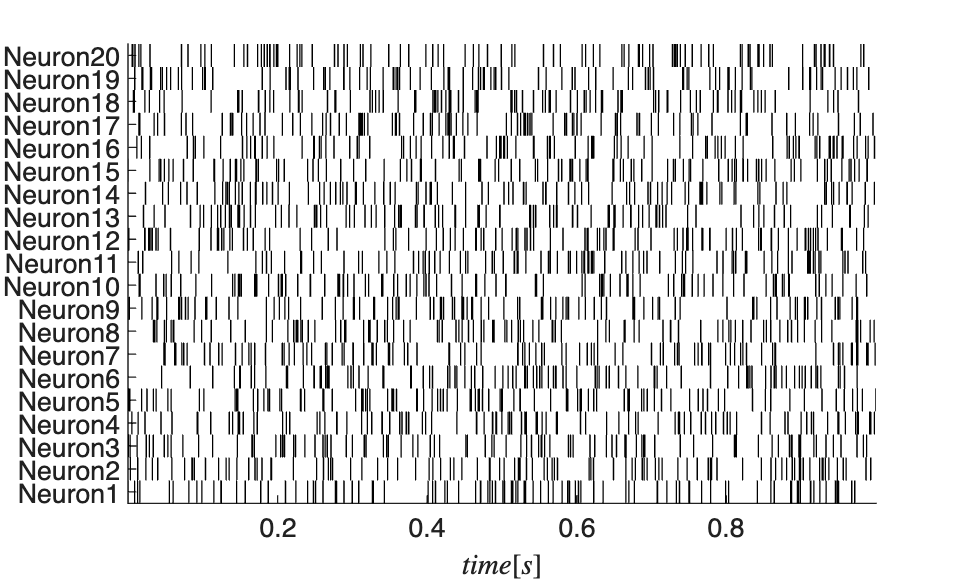

figure; spikeColl.plot;

allow only nspikeTrains 1, 4, and 7 to be visible

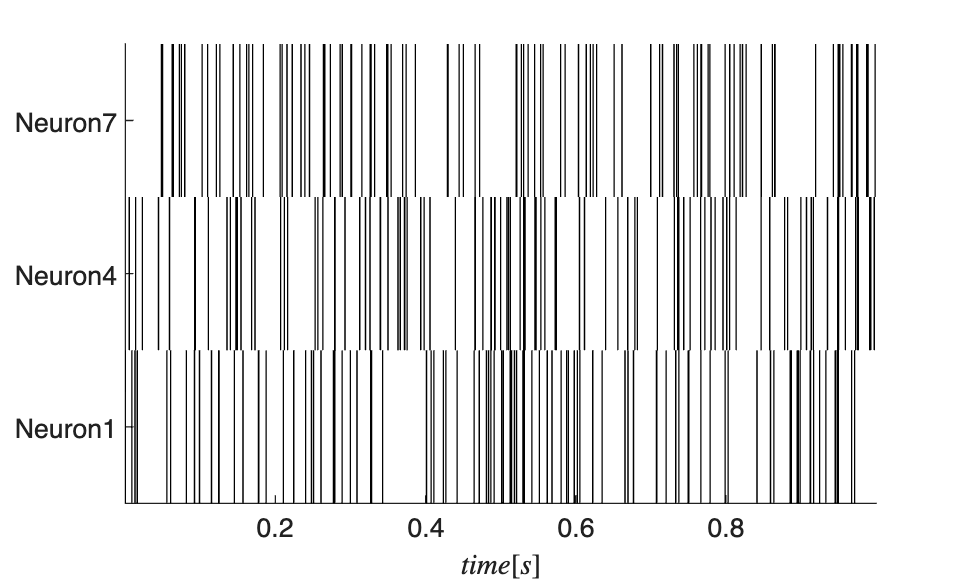

spikeColl.setMask([1 4 7]); 
figure; spikeColl.plot;

It is possible to obtain nspikeTrains from the collection;

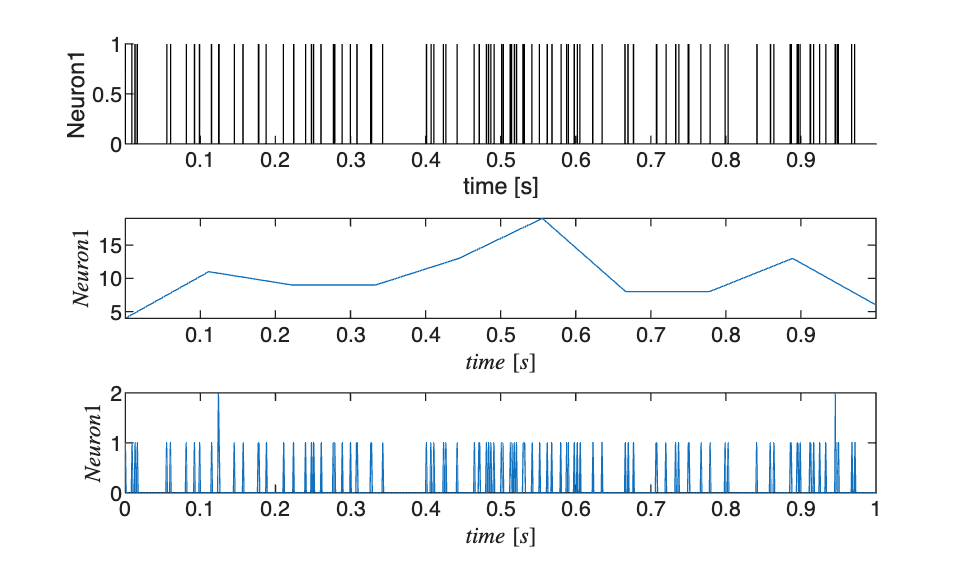

figure;
n1=spikeColl.getNST(1);     %get the first nspikeTrain in the collection
subplot(3,1,1); n1.plot;
subplot(3,1,2); n1.getSigRep.plot; %plot current sigRep

% get a SignalObj representation 1ms bins from 0 to 10 sec
s1=n1.getSigRep(.001,0,1); 
subplot(3,1,3); s1.plot;